# 3 Links Planar Manipulator

clc
close all

## Parameters

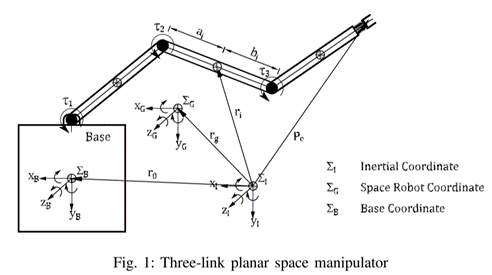

Spacecraft

baseMass = 100; % [kg]
baseSide = 2.5; % [m]

Links

link1Mass = 10;
link1Length = 2;
link2Mass = 10;
link2Length = 2;
link3Mass = 10;
link3Length = 2;

## Robotics Toolbox

### Bodies of the robot

robot = rigidBodyTree("DataFormat","column");
base = robot.Base;

spacecraft = rigidBody("spacecraft");
arm1 = rigidBody("arm1");
arm2 = rigidBody("arm2");
arm3 = rigidBody("arm3");
gripper = rigidBody("gripper");


### Collision

% Pose needed to set collision at bottom of box
collSpacecraft = collisionBox(baseSide/2, baseSide/2, baseSide/2);
collSpacecraft.Pose = trvec2tform([0 0 baseSide/2]);

colWidth = 0.1;
colLength = 0.1;

coll1 = collisionBox(colLength,colWidth, link1Length); % box: length, width, height (x,y,z)
coll1.Pose = trvec2tform([0 0 link1Length/2]);

coll2 = collisionBox(colLength,colWidth, link2Length); % box: length, width, height (x,y,z)
coll2.Pose = trvec2tform([0 0 link2Length/2]);

coll3 = collisionBox(colLength,colWidth, link3Length); % box: length, width, height (x,y,z)
coll3.Pose = trvec2tform([0 0 link3Length/2]);

collGripper = collisionSphere(0.25); % sphere: radius
collGripper.Pose = trvec2tform([0 0 0.25/2]);

addCollision(spacecraft, collSpacecraft)
addCollision(arm1,coll1)
addCollision(arm2,coll2)
addCollision(arm3,coll3)
addCollision(gripper,collGripper)

#### Joints

jntBase = rigidBodyJoint("base_joint","fixed");
jnt1 = rigidBodyJoint("jnt1","revolute");
jnt2 = rigidBodyJoint("jnt2","revolute");
jnt3 = rigidBodyJoint("jnt3","revolute");
jntGripper = rigidBodyJoint("gripper_joint","fixed");

jnt1.JointAxis = [1 0 0]; % x-axis
jnt2.JointAxis = [1 0 0];
jnt3.JointAxis = [1 0 0];
% jntGripper.JointAxis = [0 1 0] % y-axis

setFixedTransform(jnt1,trvec2tform([0 0 baseSide/2]))
setFixedTransform(jnt2,trvec2tform([-0.015 0 link1Length]))
setFixedTransform(jnt3,trvec2tform([0.015 0 link2Length]))
setFixedTransform(jntGripper,trvec2tform([0 0 link3Length]))

#### Robot Assembly

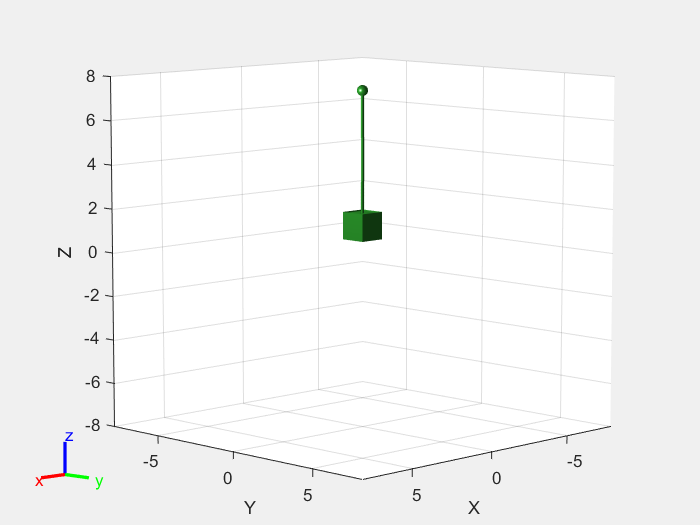

bodies = {base, spacecraft, arm1, arm2, arm3, gripper};
joints = {[], jntBase, jnt1, jnt2, jnt3, jntGripper};

figure("Name", "Assemble Robot", "Visible", "on")
for i = 2:length(bodies) % Skip base. Iterate through adding bodies and joints.
            bodies{i}.Joint = joints{i};
            addBody(robot, bodies{i}, bodies{i-1}.Name)
            show(robot,"Collisions","on","Frames","off");
            drawnow;
end

#### Details

showdetails(robot)

--------------------
Robot: (5 bodies)

 Idx         Body Name           Joint Name           Joint Type         Parent Name(Idx)   Children Name(s)
 ---         ---------           ----------           ----------         ----------------   ----------------
   1        spacecraft           base_joint                fixed                  base(0)   arm1(2)  
   2              arm1                 jnt1             revolute            spacecraft(1)   arm2(3)  
   3              arm2                 jnt2             revolute                  arm1(2)   arm3(4)  
   4              arm3                 jnt3             revolute                  arm2(3)   gripper(5)  
   5           gripper        gripper_joint                fixed                  arm3(4)   
--------------------


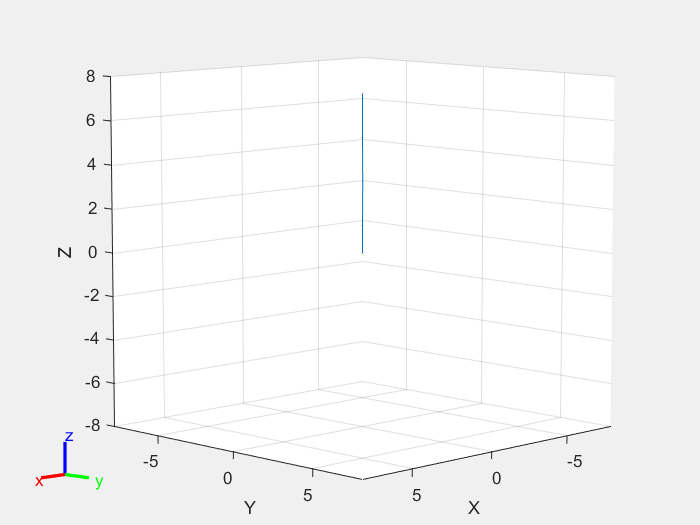

show(robot,"Collisions","off","Frames","on");

## SPART

filename='SC_3Link.urdf';

%Create robot model
[robot,robot_keys] = urdf2robot(filename);

## Robotics Tlbx from URDF

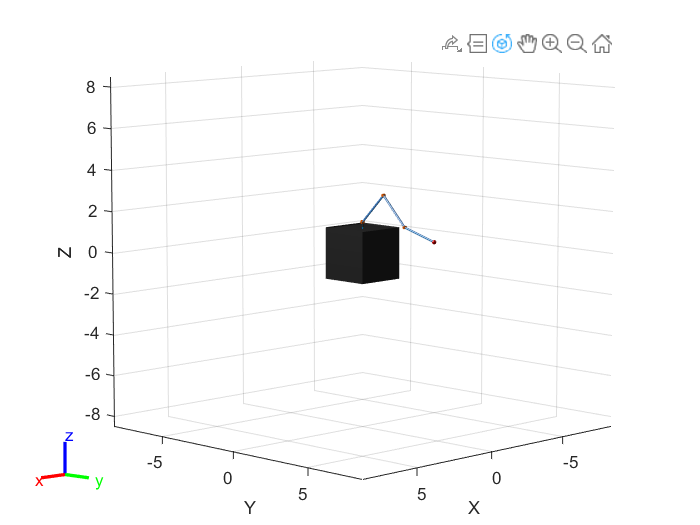

close all
filename='SC_3Link.urdf';

robot = importrobot(filename);

% Show robot model with visuals
% show(robot, 'visuals', 'on');

config = homeConfiguration(robot);

% Show robot in certain position
config(1).JointPosition = -pi/4;
config(2).JointPosition = -pi/2;
config(3).JointPosition = pi/6;

show(robot, config, 'visuals', 'on');